# Cinemática

## Cinemática Inversa

### Configuración de Eslabones con Parámetros DH

clc;
Y$Y=clear all;
syms a_i d_i theta_i alpha_i t l     % Parámetros DH
I4= sym(eye(4));                    % Transformación homogenea general
Rx = I4;                            % Transformación homogenea de rotacion sobre eje X
Rx(1:3,1:3) = [1 0 0; 0 cos(t) -sin(t); 0 sin(t) cos(t)];       
Rx = subs(Rx, t, alpha_i)

$$Rx = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(\alpha_{i}\right) & -\sin\left(\alpha_{i}\right) & 0\\ 0 & \sin\left(\alpha_{i}\right) & \cos\left(\alpha_{i}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Dx = I4;                    % Transformación homogenea de desplazamiento sobre eje X
Dx(1:3,4) = [a_i; 0; 0]

$$Dx = \left(\begin{array}{cccc} 1 & 0 & 0 & a_{i}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Rz = I4;                    % Transformación homogenea de rotacion sobre eje Z
Rz(1:3,1:3) = [cos(t) -sin(t) 0; sin(t) cos(t) 0; 0 0 1];
Rz = subs(Rz, t, theta_i)

$$Rz = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & 0\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Dz = I4;                    % Transformación homogenea de desplazamiento sobre eje Z
Dz(1:3,4) = [0; 0; d_i]

$$Dz = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Ti_j = Dz*Rz*Dx*Rx

$$Ti\_j = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\cos\left(\alpha_{i}\right)\,\sin\left(\theta_{i}\right) & \sin\left(\alpha_{i}\right)\,\sin\left(\theta_{i}\right) & a_{i}\,\cos\left(\theta_{i}\right)\\ \sin\left(\theta_{i}\right) & \cos\left(\alpha_{i}\right)\,\cos\left(\theta_{i}\right) & -\sin\left(\alpha_{i}\right)\,\cos\left(\theta_{i}\right) & a_{i}\,\sin\left(\theta_{i}\right)\\ 0 & \sin\left(\alpha_{i}\right) & \cos\left(\alpha_{i}\right) & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Proximal R y distal paralelo R o P, $R\parallel R\left(\alpha_{i\;} =0,\pi \right)$ o $R\parallel P\left(\alpha_{i\;} =0\right)$

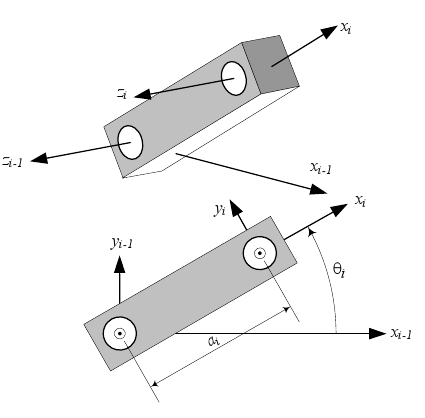

subs(Ti_j,[alpha_i, theta_i, d_i],[0, theta_i, d_i])

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & a_{i}\,\cos\left(\theta_{i}\right)\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & a_{i}\,\sin\left(\theta_{i}\right)\\ 0 & 0 & 1 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Proximal R y distal perpendicular R o P, $R\bot R\left(\alpha_{i\;} =\frac{\pi }{2}\right)$ o $R\bot P\left(\alpha_{i\;} =\frac{\pi }{2}\right)$

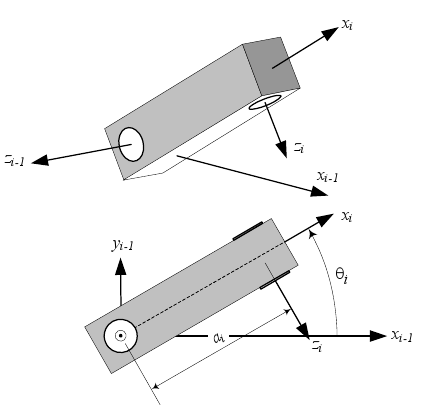

subs(Ti_j,[alpha_i, theta_i, d_i],[pi/2, theta_i, d_i])

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & 0 & \sin\left(\theta_{i}\right) & a_{i}\,\cos\left(\theta_{i}\right)\\ \sin\left(\theta_{i}\right) & 0 & -\cos\left(\theta_{i}\right) & a_{i}\,\sin\left(\theta_{i}\right)\\ 0 & 1 & 0 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Proximal R y distal ortogonal R o P, $R\vdash R\left(\alpha_{i\;} =\pm \frac{\pi }{2},a_{i\;} =0\right)$ o $\pm \left(\alpha_{i\;} =\frac{\pi }{2},a_{i\;} =0\right)$

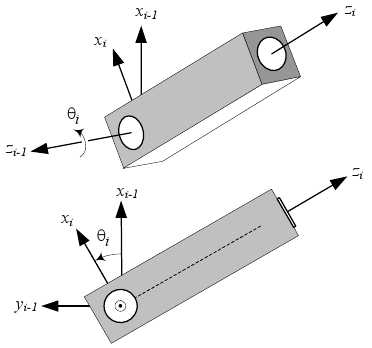

subs(Ti_j,[alpha_i, a_i, theta_i, d_i], [pi/2, 0, theta_i, d_i])

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & 0 & \sin\left(\theta_{i}\right) & 0\\ \sin\left(\theta_{i}\right) & 0 & -\cos\left(\theta_{i}\right) & 0\\ 0 & 1 & 0 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Proximal P y distal paralelo R o P, $P\parallel R\left(\alpha_{i\;} =0,\theta_{i\;} =0\right)$ o $R\parallel P\left(\alpha_{i\;} =0,\theta_{i\;} =0\right)$

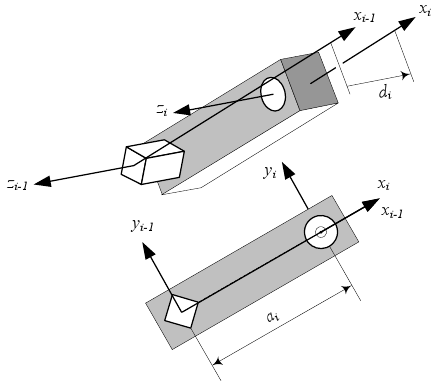

subs(Ti_j,[alpha_i, theta_i, d_i],[0, theta_i, d_i])

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & -\sin\left(\theta_{i}\right) & 0 & a_{i}\,\cos\left(\theta_{i}\right)\\ \sin\left(\theta_{i}\right) & \cos\left(\theta_{i}\right) & 0 & a_{i}\,\sin\left(\theta_{i}\right)\\ 0 & 0 & 1 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Proximal P y distal perpendicular R o P, $P\bot R\left(\alpha_{i\;} =\frac{\pi }{2},\theta_{i\;} =0\right)$ o $P\bot P\left(\alpha_{i\;} =\frac{\pi }{2},\theta_{i\;} =0\right)$

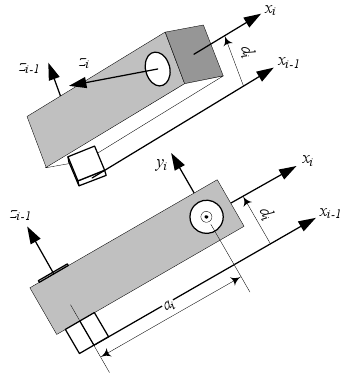

subs(Ti_j,[alpha_i, theta_i, d_i],[pi/2, theta_i, d_i])

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{i}\right) & 0 & \sin\left(\theta_{i}\right) & a_{i}\,\cos\left(\theta_{i}\right)\\ \sin\left(\theta_{i}\right) & 0 & -\cos\left(\theta_{i}\right) & a_{i}\,\sin\left(\theta_{i}\right)\\ 0 & 1 & 0 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Proximal P y distal ortogonal R o P,  $R\vdash R\left(\alpha_{i\;} =\frac{\pi }{2},a_{i\;} =0,\theta_i =0\right)$ o $R\vdash P\left(\alpha_{i\;} =\frac{\pi }{2},a_{i\;} =0,\theta_i =0\right)$

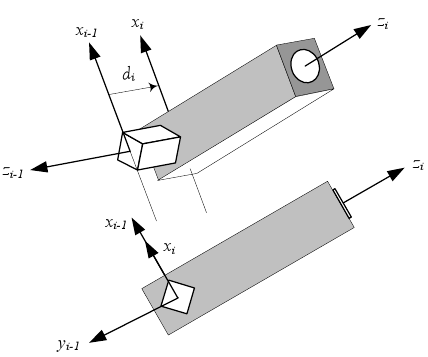

subs(Ti_j,[alpha_i, theta_i, a_i, d_i],[pi/2, 0, 0, d_i])

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & d_{i}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Ejemplo: PUMA' = $R\vdash R\parallel R$$\vdash R$

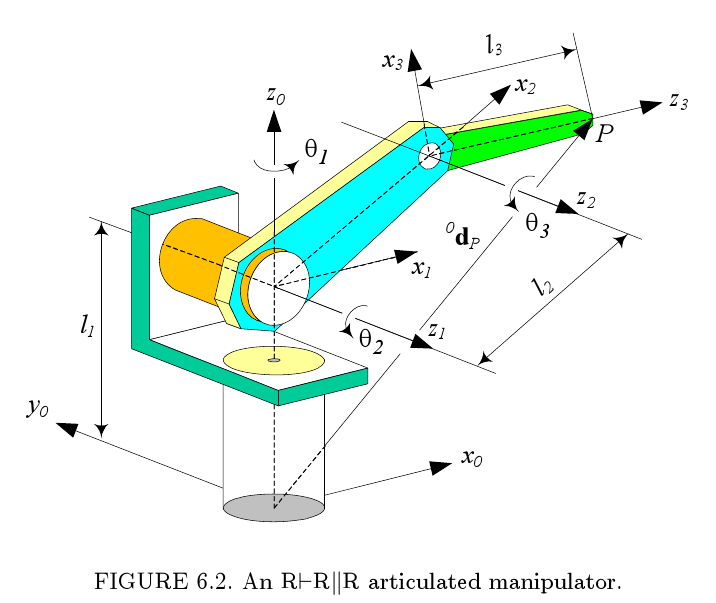


$$\left\lbrack \begin{array}{ccccc}
i & a_{i\;}  & \alpha_i  & d_i  & \theta_i \\
0\to 1 & 0 & \frac{\pi }{2} & l_1  & \theta_1 \\
1\to 2 & l_2  & 0 & 0 & \theta_2 \\
2\to 3 & 0 & \frac{\pi }{2} & 0 & \theta_3 
\end{array}\right\rbrack$$


Variables y parámetros para el robot PUMA'

syms l_1 l_2 l_3 theta_1 theta_2 theta_3
T0_1 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[0, pi/2, l_1, theta_1])      % Transformacion Homogenea 0->1

$$T0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T1_2 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[l_2, 0, 0, theta_2])         % Transformacion Homogenea 1->2

$$T1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T2_3 = subs(Ti_j,[a_i, alpha_i, d_i, theta_i],[0, pi/2, 0, theta_3])        % Transformacion Homogenea 2->3

$$T2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right) & 0\\ \sin\left(\theta_{3}\right) & 0 & -\cos\left(\theta_{3}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0_3 =(T0_1*T1_2*T2_3)          % Transformacion Homogenea 0->3

$$T0\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{1}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & 0 & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right) & l_{1}+l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0_3 = simplify(T0_3)

$$T0\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & 0 & -\cos\left(\theta_{2}+\theta_{3}\right) & l_{1}+l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

La matriz columna del punto del efector final representado en el sistema 3, se representa como la distancia del último brazo

d3_p = [0; 0; l_3; 1]       % Vector de efector final p en 3

$$d3\_p = \left(\begin{array}{c} 0\\ 0\\ l_{3}\\ 1 \end{array}\right)$$

Es posible expresar esa matriz en sistema 0 (el sistema de referencia).

d0_p = T0_3*d3_p            % Vector de efector final p en 0

$$d0\_p = \left(\begin{array}{c} l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ l_{1}-l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\\ 1 \end{array}\right)$$

El objetivo de la cinemática inversa es obtener las variables de las juntas cinemáticas en función de la posición final del efector $\theta_1 \left(d_x ,d_y ,d_z \right),\theta_2 \left(d_x ,d_y ,d_z \right),\theta_3 \left(d_x ,d_y ,d_z \right)\;$

syms d_x d_y d_z
% equ(1) = d_x == d0_p(1);
% equ(2) = d_y == d0_p(2);
% equ(3) = d_z == d0_p(3);
% sol = solve(equ,[theta_1, theta_2, theta_3])

### Método de desacoplamiento:

Para este robot en específico, con juntas cinemáticas rotacionales, podemos arreglar los términos de la matriz ${}^0{\mathit{\mathbf{d}}}_p$ para obtener una relación trigonometrica $a\;\sin \left(\theta \right)+b\;\cos \left(\theta \right)=c$

syms a b c
equ0 = a*cos(theta_i) + b*sin(theta_i) - c == 0;
sol0 = solve(equ0, [theta_i])

$$sol0 = \left(\begin{array}{c} -\log\left(\frac{c+\sqrt{-a^{2}-b^{2}+c^{2}}}{a-b\,\mathrm{i}}\right)\,\mathrm{i}\\ -\log\left(\frac{c-\sqrt{-a^{2}-b^{2}+c^{2}}}{a-b\,\mathrm{i}}\right)\,\mathrm{i} \end{array}\right)$$

equT = [d_x; d_y; d_z; 1] == d0_p

$$equT = \left(\begin{array}{c} d_{x}=l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ d_{y}=l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ d_{z}=l_{1}-l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\sin\left(\theta_{2}\right)\\ 1=1 \end{array}\right)$$

Para el giro $\theta_1$, se puede manipular $d_x$ y $d_y$, obtener la relación $a\;\sin \left(\theta \right)+b\;\cos \left(\theta \right)=c$

equ1 = equT(1)*sin(theta_1) - equT(2)*cos(theta_1)

$$equ1 = d_{x}\,\sin\left(\theta_{1}\right)-d_{y}\,\cos\left(\theta_{1}\right)=\sin\left(\theta_{1}\right)\,\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)-\cos\left(\theta_{1}\right)\,\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)$$

equ1 = (lhs(equ1)) == simplify(rhs(equ1))

$$equ1 = d_{x}\,\sin\left(\theta_{1}\right)-d_{y}\,\cos\left(\theta_{1}\right)=0$$

sol1 = coeffs(lhs(equ1), [cos(theta_1), sin(theta_1)])

$$sol1 = \left(\begin{array}{cc} d_{x} & -d_{y} \end{array}\right)$$

Por tanto

t1 = subs(sol0, [a, b, c], [sol1(1), sol1(2), 0])

$$t1 = \left(\begin{array}{c} -\log\left(\frac{\sqrt{-{d_{x}}^{2}-{d_{y}}^{2}}}{d_{x}+d_{y}\,\mathrm{i}}\right)\,\mathrm{i}\\ -\log\left(-\frac{\sqrt{-{d_{x}}^{2}-{d_{y}}^{2}}}{d_{x}+d_{y}\,\mathrm{i}}\right)\,\mathrm{i} \end{array}\right)$$

Para el ángulo $\theta_2$, lo que se busca es tener eliminar los terminos que contengan $\theta_3$

equ2 = equT(1)*cos(theta_1) + equT(2)*sin(theta_1)

$$equ2 = d_{x}\,\cos\left(\theta_{1}\right)+d_{y}\,\sin\left(\theta_{1}\right)=\cos\left(\theta_{1}\right)\,\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\right)+\sin\left(\theta_{1}\right)\,\left(l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right)+l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)$$

equ2 = (lhs(equ2)) == simplify(rhs(equ2))

$$equ2 = d_{x}\,\cos\left(\theta_{1}\right)+d_{y}\,\sin\left(\theta_{1}\right)=l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{2}\,\cos\left(\theta_{2}\right)$$

equ2 = equ2 - l_2*cos(theta_2)

$$equ2 = d_{x}\,\cos\left(\theta_{1}\right)-l_{2}\,\cos\left(\theta_{2}\right)+d_{y}\,\sin\left(\theta_{1}\right)=l_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)$$

equ3 = (equT(3) - l_1 - l_2*sin(theta_2))*(-1)

$$equ3 = l_{1}-d_{z}+l_{2}\,\sin\left(\theta_{2}\right)=l_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)$$

Si equ2 y equ3 los elevamos al cuadrado y sumamos, obtenemos una ecuación sin terminos en $\theta_3$

equ4 = simplify(equ2^2+equ3^2)

$$equ4 = {\left(l_{1}-d_{z}+l_{2}\,\sin\left(\theta_{2}\right)\right)}^{2}+{\left(d_{x}\,\cos\left(\theta_{1}\right)-l_{2}\,\cos\left(\theta_{2}\right)+d_{y}\,\sin\left(\theta_{1}\right)\right)}^{2}={l_{3}}^{2}$$

equ4 = simplify((expand(equ4)))

$$equ4 = {d_{x}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}+\sin\left(2\,\theta_{1}\right)\,d_{x}\,d_{y}-{d_{y}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}+{d_{y}}^{2}+{d_{z}}^{2}+{l_{1}}^{2}+2\,\sin\left(\theta_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}={l_{3}}^{2}+2\,d_{z}\,l_{1}+2\,d_{z}\,l_{2}\,\sin\left(\theta_{2}\right)+2\,d_{x}\,l_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+2\,d_{y}\,l_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)$$

equ4 = collect(equ4 - rhs(equ4),[cos(theta_2), sin(theta_2)])

$$equ4 = \left(-2\,d_{x}\,l_{2}\,\cos\left(\theta_{1}\right)-2\,d_{y}\,l_{2}\,\sin\left(\theta_{1}\right)\right)\,\cos\left(\theta_{2}\right)+\left(2\,l_{1}\,l_{2}-2\,d_{z}\,l_{2}\right)\,\sin\left(\theta_{2}\right)+{d_{x}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}+\sin\left(2\,\theta_{1}\right)\,d_{x}\,d_{y}-{d_{y}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}+{d_{y}}^{2}+{d_{z}}^{2}-2\,d_{z}\,l_{1}+{l_{1}}^{2}+{l_{2}}^{2}-{l_{3}}^{2}=0$$

sol2 = coeffs(lhs(equ4), [cos(theta_2), sin(theta_2)])

$$sol2 = \left(\begin{array}{ccc} -2\,d_{z}\,l_{1}+{d_{x}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}-{d_{y}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}+{d_{y}}^{2}+{d_{z}}^{2}+{l_{1}}^{2}+{l_{2}}^{2}-{l_{3}}^{2}+\sin\left(2\,\theta_{1}\right)\,d_{x}\,d_{y} & 2\,l_{1}\,l_{2}-2\,d_{z}\,l_{2} & -2\,d_{x}\,l_{2}\,\cos\left(\theta_{1}\right)-2\,d_{y}\,l_{2}\,\sin\left(\theta_{1}\right) \end{array}\right)$$

t1 = subs(sol0, [c, b, a], [-sol2(1), sol2(2), sol2(3)])

$$t1 = \begin{array}{l} \left(\begin{array}{c} -\log\left(\frac{\sigma_{5}-2\,d_{z}\,l_{1}-\sigma_{4}+{d_{y}}^{2}+{d_{z}}^{2}+{l_{1}}^{2}+{l_{2}}^{2}-{l_{3}}^{2}-\sigma_{2}+\sigma_{1}}{\sigma_{3}}\right)\,\mathrm{i}\\ -\log\left(\frac{\sigma_{5}-2\,d_{z}\,l_{1}-\sigma_{4}+{d_{y}}^{2}+{d_{z}}^{2}+{l_{1}}^{2}+{l_{2}}^{2}-{l_{3}}^{2}+\sigma_{2}+\sigma_{1}}{\sigma_{3}}\right)\,\mathrm{i} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{x}\,d_{y}\,\sin\left(2\,\theta_{1}\right)\\ \sigma_{2}=\sqrt{{\left(\sigma_{5}+\sin\left(2\,\theta_{1}\right)\,d_{x}\,d_{y}-\sigma_{4}+{d_{y}}^{2}+{d_{z}}^{2}-2\,d_{z}\,l_{1}+{l_{1}}^{2}+{l_{2}}^{2}-{l_{3}}^{2}\right)}^{2}-{\left(2\,d_{z}\,l_{2}-2\,l_{1}\,l_{2}\right)}^{2}-{\left(\sigma_{7}+\sigma_{6}\right)}^{2}}\\ \sigma_{3}=\sigma_{7}+\sigma_{6}-2\,d_{z}\,l_{2}\,\mathrm{i}+2\,l_{1}\,l_{2}\,\mathrm{i}\\ \sigma_{4}={d_{y}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\\ \sigma_{5}={d_{x}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\\ \sigma_{6}=2\,d_{y}\,l_{2}\,\sin\left(\theta_{1}\right)\\ \sigma_{7}=2\,d_{x}\,l_{2}\,\cos\left(\theta_{1}\right) \end{array}$$

Dado que ya tenemos $\theta_1$ y $\theta_2$, podemos obtener $\theta_3$, dividiendo equ2 y equ3

equ5 = (equ2/equ3)

$$equ5 = \frac{d_{x}\,\cos\left(\theta_{1}\right)-l_{2}\,\cos\left(\theta_{2}\right)+d_{y}\,\sin\left(\theta_{1}\right)}{l_{1}-d_{z}+l_{2}\,\sin\left(\theta_{2}\right)}=\frac{\sin\left(\theta_{2}+\theta_{3}\right)}{\cos\left(\theta_{2}+\theta_{3}\right)}$$

### Método de numérico:


$$\left\lbrack \begin{array}{ccccc}
i & a_{i\;}  & \alpha_i  & d_i  & \theta_i \\
0\to 1 & 0 & \frac{\pi }{2} & l_1  & \theta_1 \\
1\to 2 & l_2  & 0 & 0 & \theta_2 \\
2\to 3 & 0 & \frac{\pi }{2} & 0 & \theta_3 
\end{array}\right\rbrack$$


clc;
clear all;


Distancias de los eslabones

l_1 = 0.3;      l_2 = 0.4;          l_3 = 0.3;


Parametros DH $a_i ,{\;\alpha }_i ,d_i ,\theta_i$

dhparams = [0,   pi/2,     l_1,      0;
            l_2,   0,       0,       0;
            0,   pi/2,      0,       0;
            0,     0,       l_3,     0];  


Estructura de datos para junta cinemática

cougar = rigidBodyTree;


Estruturas para cuerpos y juntas

cuerpo = {'base', 'tronco', 'brazo', 'a-brazo', 'muñon'};
    junta = {'cintura', 'hombro', 'codo', 'muñeca'};
tipoJunta = {'revolute', 'revolute', 'revolute', 'fixed'};



Construccion del robot

for i = 1:length(junta)
    body(i) = rigidBody(cuerpo{i+1});
    jnt(i) = rigidBodyJoint(junta{i}, tipoJunta{i});
    setFixedTransform(jnt(i),dhparams(i,:),'dh');
    body(i).Joint = jnt(i);
    addBody(cougar,body(i),cuerpo{i})
    jnt(i).ChildToJointTransform
end

ans =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.3000
         0         0         0    1.0000


ans =     1.0000         0         0    0.4000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


ans =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


ans =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.3000
         0         0         0    1.0000


Despliega los resultados de la cadena cinemática

showdetails(cougar)

--------------------
Robot: (4 bodies)

 Idx      Body Name     Joint Name     Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------     ----------     ----------      ----------------   ----------------
   1         tronco        cintura       revolute               base(0)   brazo(2)  
   2          brazo         hombro       revolute             tronco(1)   a-brazo(3)  
   3        a-brazo           codo       revolute              brazo(2)   muñon(4)  
   4          muñon         muñeca          fixed            a-brazo(3)   
--------------------


Definir la trayectoria a seguir por el muñon

t = (0:0.2:10)';        % Tiempo
N_t = length(t);        % Numero de elementos de la matriz tiempo
c = [0.2 0.3 0];          % Centro del circulo
r = 0.2;                % Radio del cirulo
theta = t*(2*pi/t(end));        % 'Angulo de avance en el circulo
p = c + r*[cos(theta) sin(theta) zeros(size(theta))];       % El famoso punto p

Configuración del robot, es decir, los valores que toma cada una de las variables de las juntas $q=\left\lbrack \begin{array}{cccc}
\theta_1 \left(t\right) & \theta_2 \left(t\right) & \ldotp \ldotp \ldotp  & \theta_n \left(t\right)
\end{array}\right\rbrack$

q0 = homeConfiguration(cougar);     % Configuración inicial 
ndof = length(q0);                  % Grados de libertad

Solucionador para cinemática inversa

ik = inverseKinematics('RigidBodyTree', cougar);        %Recibe como argumentos el tipo de objeto y el objeto, en este caso una cadena cinematica
VecPesos = [0, 0, 0, 1, 1, 1];     % Valores entre 0-1, son las tolerancias de la pose, 3 para orientación y 3 para posición
Effector = 'muñon';                % Cuerpo donde se miden las transformaciones del punto final

Iterador

q{1} = q0;              % Condiciones iniciles, configuracion inicial
for i = 1:N_t
    q{i+1} = ik(Effector, trvec2tform(p(i,:)), VecPesos, q{i});  % Se obtiene la nueva configuración q{i+1}, utilizando la configuración anterior q{i}
    tF = getTransform(cougar, q{i+1}, Effector);
    for j = 1:ndof      % Se obtienen los valores de las juntas y las posiciones del efector para graficarlas
        theta(i,j) = q{i}(j).JointPosition; 
        Pnt(i,j) = tF(j,4);
    end
end

Dibujos

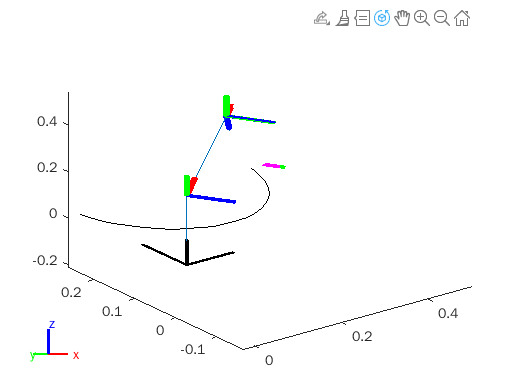

% close all;
figure(1)                                           
plot3(Pnt(:,1), Pnt(:,2), Pnt(:,3), 'r');               % Grafica los puntos del efector en rojo
hold on
plot3(p(:,1), p(:,2), p(:,3),'k');                      % Grafica los puntos de la trayectoria en negro
axis([ -0.0257    0.5018   -0.1640    0.2610   -0.2145    0.5480])

% keyboard;
for i = 1:N_t
    show(cougar, q{i+1}, 'PreservePlot', false);        % Despliga la configuracion del robot para cada punto de la trayectoria
    drawnow
    waitfor(rateControl(20));
end
show(cougar, q{i+1}, 'PreservePlot', true);        

hold off

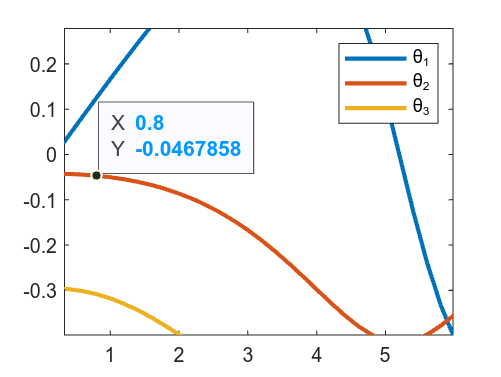

figure(2)
plot(t, theta(:,1), t, theta(:,2), t, theta(:,3), 'lineWidth', 2);      % Grafica los valores del juntas cinematicas en funcion del tiempo
legend('\theta_1', '\theta_2', '\theta_3');

% axis tight
